# Model Inserted Earbud

In this example, you analyze how each earbud component affects the overall frequency response. 

The microspeaker used in this model takes the input voltage and coverts into pressure through the electromechanical and mechanical-acoustic coupling. The electromechanical coupling obeys the Lorentz Force law that converts the induced current into force driving the diaphragm and voice coil: 


$$F=-\textrm{Bli}$$


The coupling between the mechanical and acoustic domain is realized through an area transformer. The force driving the particles on the diaphragm surface becomes the induced pressure. The velocity of the particles, which is equal to the velocity of the moving diaphragm, becomes the volume velocity. 


$$p=\frac{F}{A}$$



$$U=\textrm{vA}$$


You analyze the rest of the model in the acoustic domain where various components are modeled as their lumped elements representation. The lumped model is assumed to be valid is when the dimensions are much smaller than the wavelength of the frequencies of interest. 

## Open the Lumped Model

Open the model.

model = "InsertedEarbud";
open_system(model);

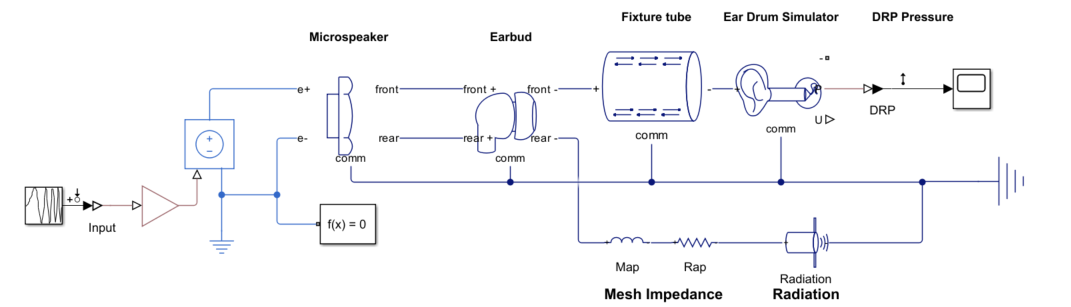

This model applies an input voltage of 0.179V, which is the required voltage of a standardized 1 mW testing condition for a 32 ohm speaker. The microspeaker used in the earbud comprises:

- A front cover with multiple holes.

- A front cavity between the cover and the diaphragm.

- The mechanical properties of the diaphragm.

- The electrical properties of the moving coil.

- A speaker frame.

- A rear cavity between the diaphragm and the frame.

- Vents on the frame.

For more details, see the `Microspeaker` example model.

The `Ear Drum Simulator` block models the response of a testing jig that follows the IEC-60318-4 Standard. The IEC 60318-4 Standard, formerly IEC 60711, specifies the response of a typical human ear up to 10kHz. "DRP" stands for "Drum Reference Point", which refers to the pressure measured at the ear drum. See the `EarDrumSimulator` example model for more details. 

The jig and the earbud are coupled by a fixture modeled as a cylindrical tube with thermoviscous losses. The detailed configurations of the tube are shown in the figure below. 

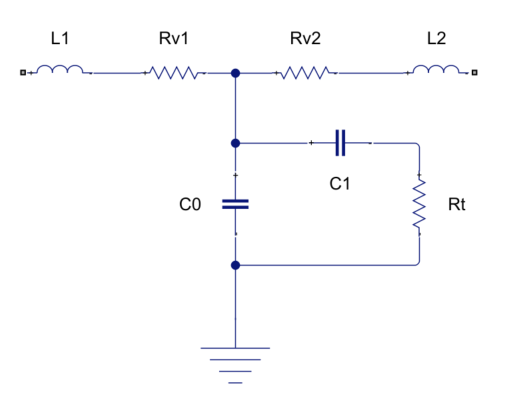


$$$L_1 =L_2 = \frac{\rho l}{2A}$$$



$$$R_{v1}=R_{v2}=\frac{8\pi\rho\nu l}{2A^2}$$$



$$$C_0=\frac{V}{\rho c^2}$$$



$$$C_1 =C_0(\gamma-1)$$$



$$$R_t=\frac{\rho^2 c^2 C_p}{8\pi \kappa(\gamma-1)l}$$$


Where:

- $$\rho$$ is the density of air $$1.21 kg/m^3$$.

- $$\nu$$ is the viscosity of air $$15.68\times10^{-6} m^2/s$$.

- $$c$$ is the sound speed in air $$343m/s$$.

- $$\gamma$$ is the ratio of specific heat for air.

- $$\kappa$$ is the thermal conductivity of air $$0.0257 W/mK$$.

- $$C_p$$ is the specific heat of air at constant pressure $$1.01 \times10^3 kJ/kgK$$.

- $ $l$$ is the length of the tube.

- $$A$$ is the cross sectional area of the tube.

- $$V$$ is the volume of the tube.

The "Radiation" represents the air loading on the opening. The air mass, represented by an inductor, and radiation damping, represented by a resistor, are connected in parallel:


$$M_{rad}=\frac{B_i \rho r}{4 \pi r^2}$$



$$$R_{rad}=\frac{B_i^2 \rho c}{B_r4 \pi r^2}$$$


$r$ is the opening radius.

For the circular flanged opening:

- 
$$$B_i =\frac{8}{3 \pi}$$$


- 
$$$B_r =0.5$$$


## Linearize Model

This example sets the input perturbation point and output measurement point for analysis to be done in the frequency domain instead of time domain. Extracting the real time simulation outputs and performing Fourier Transform will also returns the same results.

Set the model linearizing points

io(1) = linio("InsertedEarbud/Chirp Signal",1, "input");        % input perturbation
io(2) = linio("InsertedEarbud/DRP",1, "output");                % output measurement

Use the `linearize` function to linearize the model and the `bode` function to extract the magnitude, phase, and frequency information. 

linsys = linearize(model,io);           % linearize model
[mag, phase, wout] = bode(linsys);      % extract results

Note that the frequency information is in rad/s. Divide by $2\pi $to convert to hertz. The sound pressure level in dB is given by:


$$\textrm{dBSPL}=20\;\log \;\left(\frac{p_{\textrm{rms}} }{p_{\textrm{ref}} }\right)$$


where the reference pressure in air is $p_{ref}=20\mu Pa$.

p_ref = 20e-6;          % reference pressure in air (Pa)
freq = wout./(2*pi);    % convert radiance to frequency
SPL = 20.*log10(mag(:)./p_ref);         % calculate dBSPL
deg = phase(:);                         % extract phase 

Plot the results.

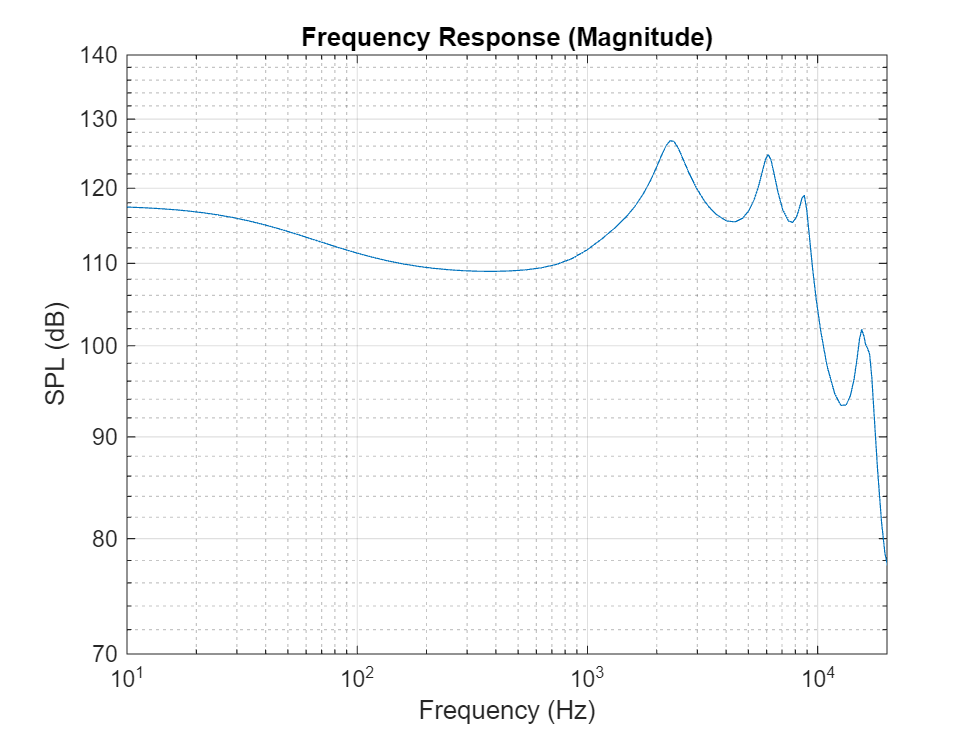

fig1 = figure;
loglog(freq, SPL);
xlim([10 20e3]);
ylim([70 140]);
title("Frequency Response (Magnitude)");
xlabel("Frequency (Hz)");
ylabel("SPL (dB)");
grid on
hold on

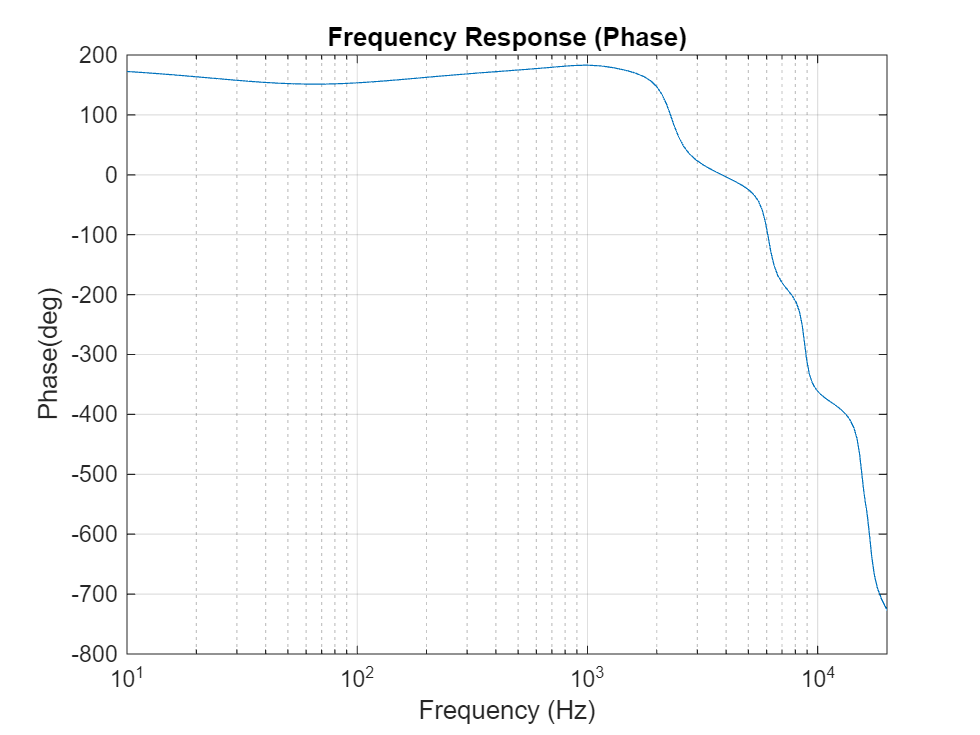

fig2 = figure;
semilogx(freq, deg);
xlim([10 20e3]);
title("Frequency Response (Phase)");
xlabel("Frequency (Hz)");
ylabel("Phase(deg)");
grid on
hold on

## Remove Front Vent

To see how the front vent, or front leakage hole, impacts the frequency response, the model is set to the extreme condition, where the front vent is completely blocked. The front vent can be seen as a high pass acoustic filter where the transmitted power downstream is roughly given by:


$$T_w \approx {\left\lbrack 1+{\left(\frac{\pi a^2 }{2S_1 k\left(L+1\ldotp 43a\right)}\right)}^2 \right\rbrack }^{-1\;}$$


Where:

- $S_1$ is the cross sectional area of the main sound tube.

- $a$ is the radius of the side vents or orifices.

- $L$ is the length of the vents.

- $k=\frac{\omega }{c}$ is the wave number of the given frequency and $$c$$ is the sound speed in air $$343m/s$$.

From the equation, the transmitted power approaches 1 (sound is fully transmitted from the input to output) as the frequency increases for a given vent size. On the other hand, the transmitted power is inversely proportional to the opening size of the vents for a given frequency. Thus the low frequency response is expected to increase when the front vent is blocked ($a=0$). 

Exclude the front vent.

path = model+"/Earbud";                               % specify component block
condition = "acoustic.enum.Bud_FrontVent(1)";         % enumeration condition for excluding front vent
set_param(path,"fvent_earbud", condition);            % set font vent parameter to condition

Linearize the modified model.

linsys = linearize(model,io);           % linearize model
[mag, phase, wout] = bode(linsys);      % extract results
freq = wout./(2*pi);                    % convert radiance to frequency
SPL = 20.*log10(mag(:)./p_ref);         % calculate dBSPL
deg = phase(:);                         % extract phase 

Plot the results.

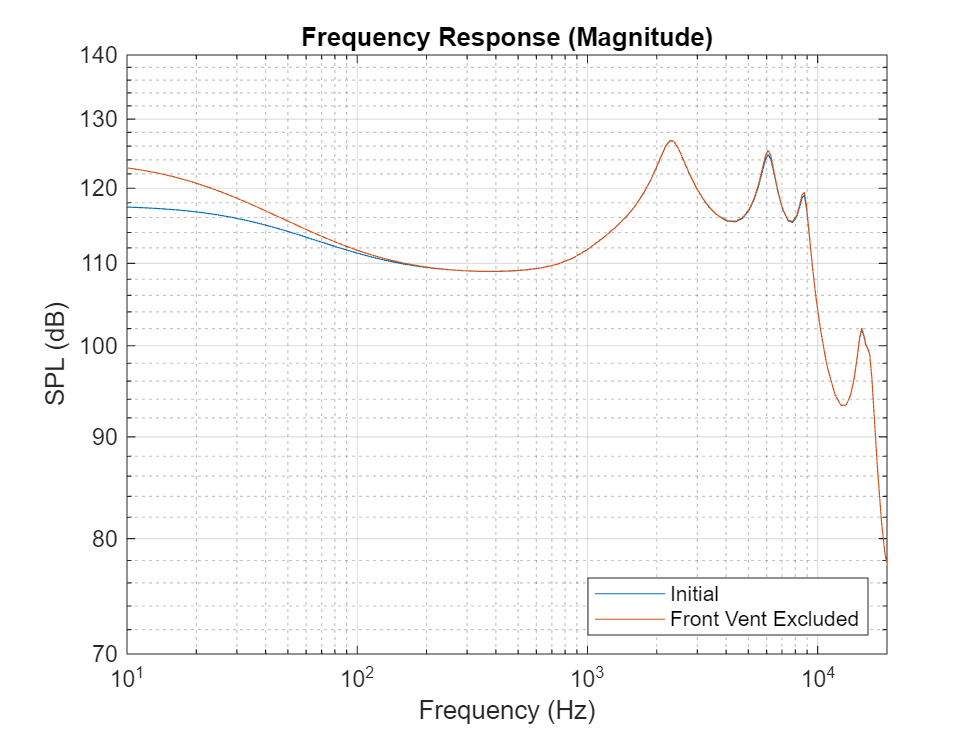

figure(fig1)
loglog(freq, SPL);
legend("Initial", ...
    "Front Vent Excluded", ...
    "Location","southeast");
hold on

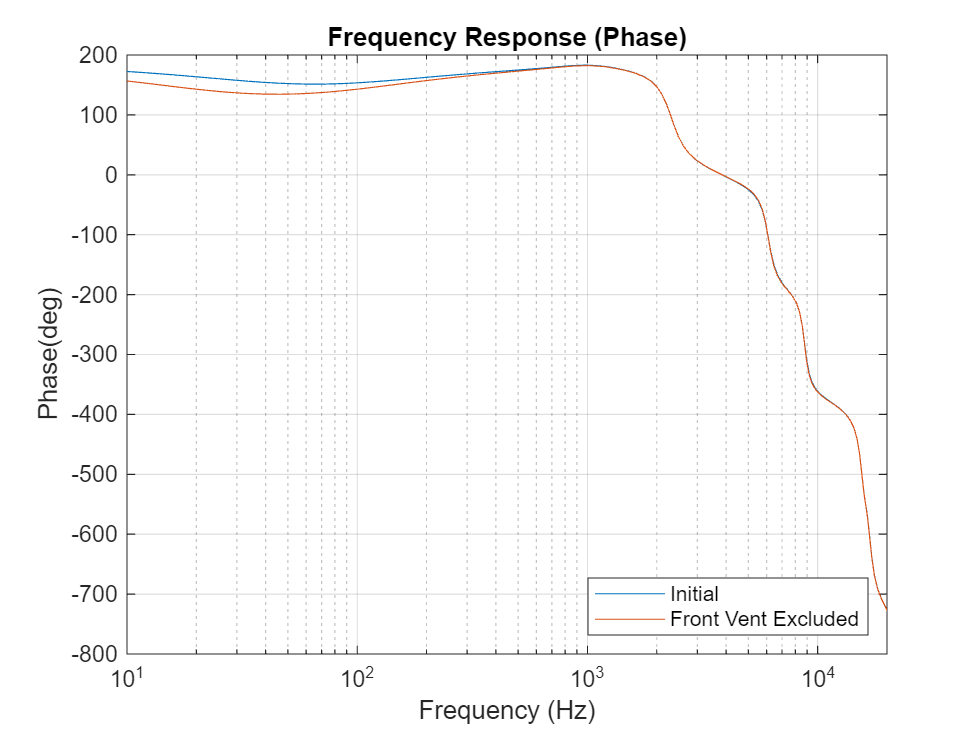

figure(fig2)
semilogx(freq, deg);
legend("Initial", ...
    "Front Vent Excluded", ...
    "Location","southeast");
hold on

## Reduce Rear Cavity Volume

In this example, any change made is compared to the initial condition. Restore the front vent before you make further changes.

condition = "acoustic.enum.Bud_FrontVent(2)";         % enumeration condition for including front vent
set_param(path,"fvent_earbud", condition);            % set front vent parameter back to previous state 

To see how the rear cavity volume impacts the frequency response, the volume is reduced to 1% of its default value. The cavity is related to the air compliance, which is also related to the resonance frequency given by:


$$f_0 =\frac{1}{2\pi \;}\sqrt{\frac{1\;}{\textrm{mC}}}$$


Where 

- $m$ is the effective mass.

- $C$ is the effective compliance (inverse of stiffness).

A small volume of air can be seen as a lumped air spring where its compliance can be calculated by:

$C_a=\frac{V}{\rho c^2 }$.

Where

- $V$ is the volume of the cavity.

- $$\rho$$ is the density of air $$1.21 kg/m^3$$.

- $$c$$ is the sound speed in air $$343m/s$$.

From the equation, the compliance will decrease as the volume decrease. Thus the resonance peak is expected to shift to a higher frequency (becomes stiffer) when the change is made. 

Decrease the rear cavity.

set_param(path,'bud_Vb', 'Vbud*1e-2');         % set parameter to decrease the rear cavity by a factor of 0.01

Linearize the modified model.

linsys = linearize(model,io);           % linearize model
[mag, phase, wout] = bode(linsys);      % extract results
freq = wout./(2*pi);                    % convert radiance to frequency
SPL = 20.*log10(mag(:)./p_ref);         % calculate dBSPL
deg = phase(:);                         % extract phase 

Plot the results.

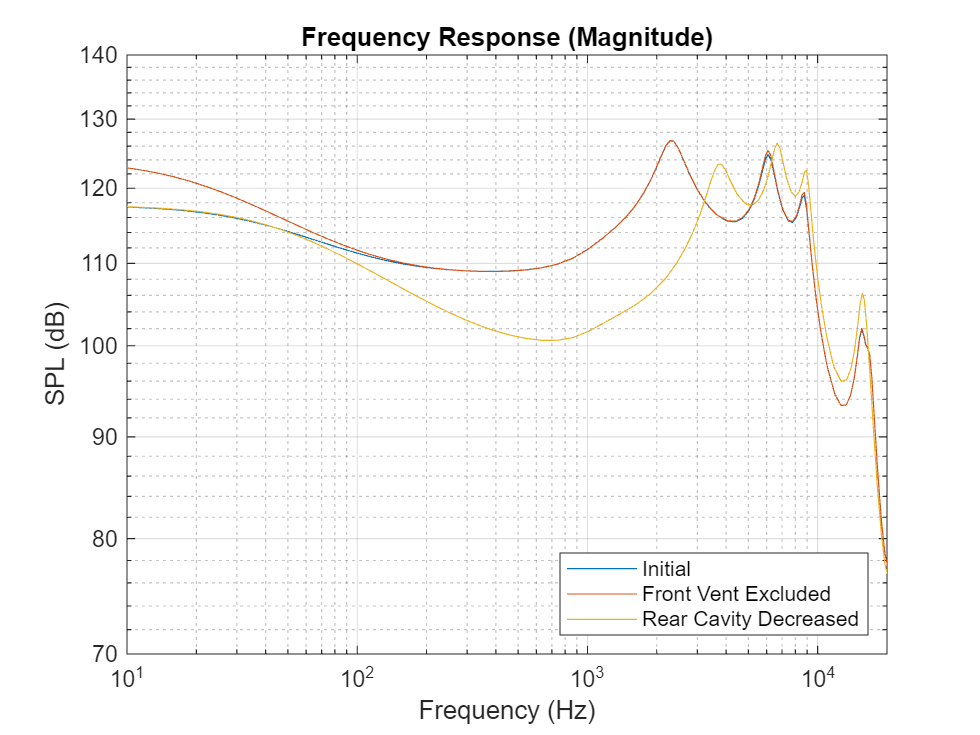

figure(fig1)
loglog(freq, SPL);
legend("Initial", ...
    "Front Vent Excluded", ...
    "Rear Cavity Decreased", ...
    "Location","southeast");
hold on

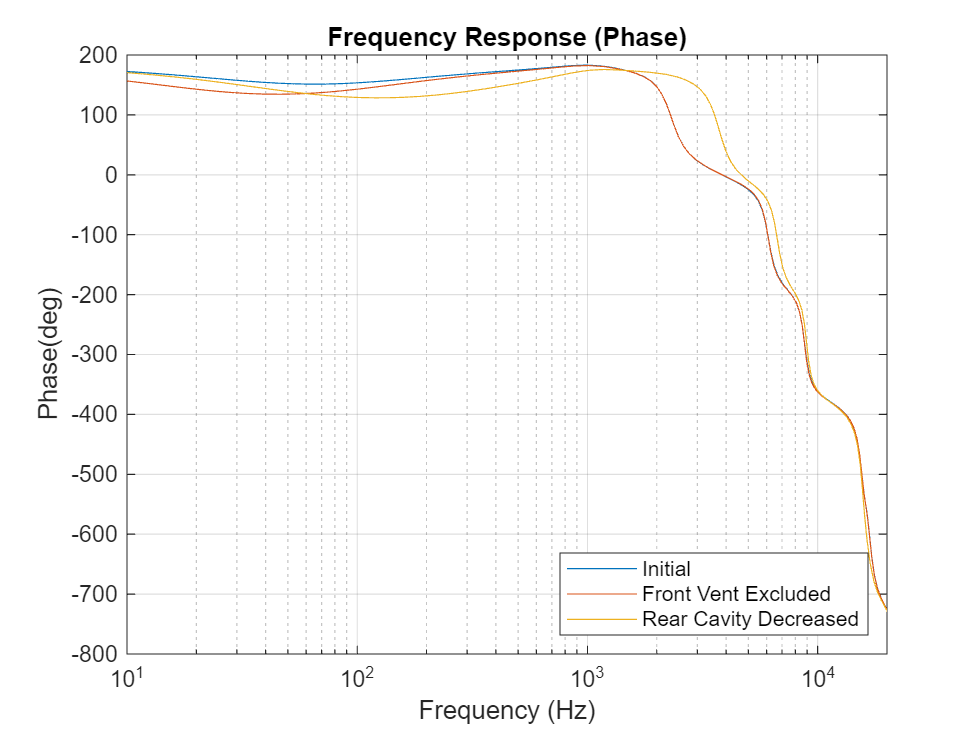

figure(fig2)
semilogx(freq, deg);
legend("Initial", ...
    "Front Vent Excluded", ...
    "Rear Cavity Decreased", ...
    "Location","southeast");
hold on

## Remove Rear Vent

Next, you block the rear vent to see the impact on the frequency response. 

The rear vent can be equated as the tuning port of a bass reflex speaker. It also releases the pressure build up the in rear cavity and reduces the additional stiffness added to the diaphragm from the air cavity. Thus, when the rear vent is blocked, the low frequency is expected to decreased as the diaphragm becomes stiffer. 

First, restore the model to its previous state.

set_param(path,"bud_Vb", "Vbud");       % set rear cavity parameter back to previous state 

Next, exclude the rear vent.

condition = "acoustic.enum.Bud_RearVent(1)";          % enumeration condition for excluding rear vent
set_param(path,"rvent_earbud", condition);              % set rear vent parameter to condition 

Comment out the acoustic mass and resistance from the cloth and radiation.

path1 = model+ "/Map";
path2 = model+ "/Rap";
path3 = model+ "/Radiation";
set_param(path1,"Commented","on");
set_param(path2,"Commented","on");
set_param(path3,"Commented","on");

Linearize the modified model.

linsys = linearize(model,io);           % linearize model
[mag, phase, wout] = bode(linsys);      % extract results
freq = wout./(2*pi);                    % convert radiance to frequency
SPL = 20.*log10(mag(:)./p_ref);         % calculate dBSPL
deg = phase(:);                         % extract phase 

Plot the results.

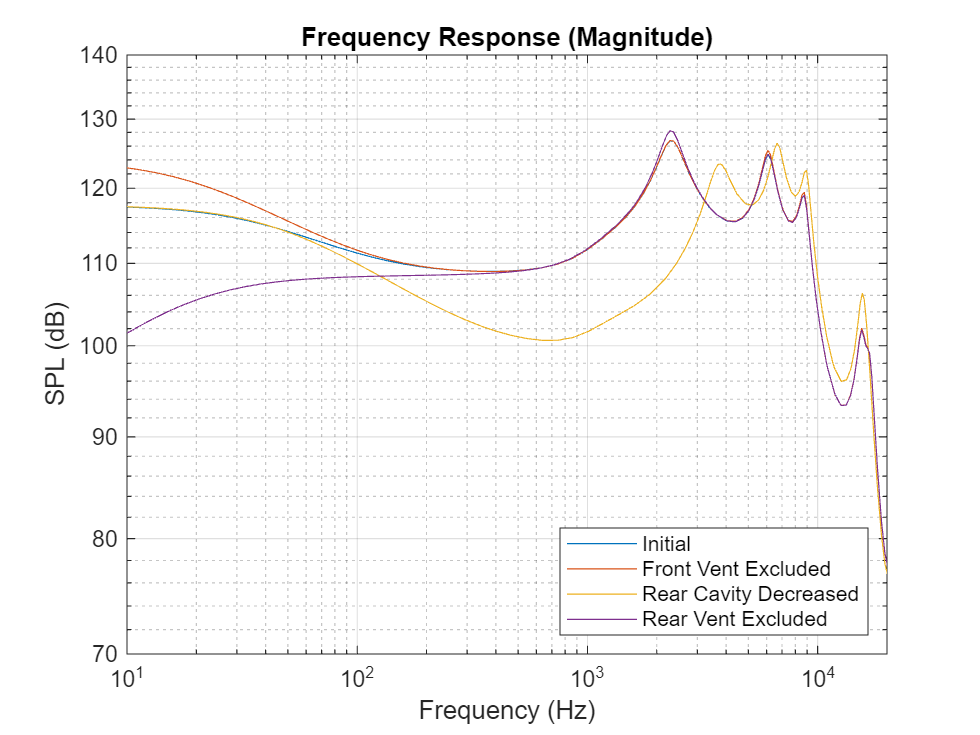

figure(fig1)
loglog(freq, SPL);
legend("Initial", ...
    "Front Vent Excluded", ...
    "Rear Cavity Decreased", ...
    "Rear Vent Excluded", ...
    "Location","southeast");
hold on

Notice that he slight roll off in the low frequency region is due to the front vent and leakage in the front cavity (sound tube). If the front cavity is perfectly sealed, the low frequency response would be flat. 

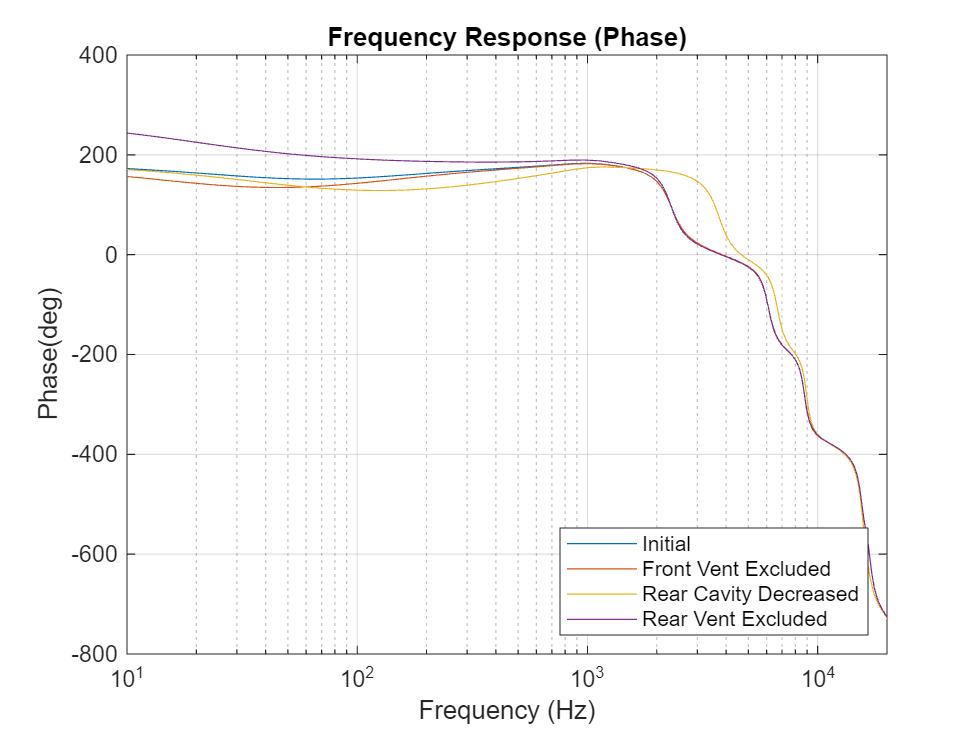

figure(fig2)
semilogx(freq, deg);
legend("Initial", ...
    "Front Vent Excluded", ...
    "Rear Cavity Decreased", ...
    "Rear Vent Excluded", ...
    "Location","southeast");
hold on

## Reduce Rear Vent Damping

In this example, the earbud is modeled to have a damping mesh covering the rear vent opening. The "Mesh Impedance" is modeled as a series of air inertance (inductor) and air resistance (resistor). The inertance represents the air mass inside the tiny holes across the mesh and the air resistance represents the viscous loss as the air flow through the holes. 

The values are given by:


$$$M_{a}=\frac{4\rho l}{3AN}$$$



$$$R_{a} = \frac{8\pi\rho\nu l}{A^2N}$$$


Where:

- $\;l\;$is the length (thickness) of the holes.

- $A$ is the opening area of the individual holes.

- $N$ is the number of holes.

Damping tends to smooth out the response around the resonance and shift the resonance to higher frequency.  Here, the default value for the air resistance is $5\ldotp 84\times {10}^8 \;\textrm{Pa}\cdot s/m^{3\;}$. To see the impact on the pressure response, the mesh damping is changed to $1\;\textrm{Pa}\cdot s/m^{3\;}$.

Restore the model defaults.

condition = "acoustic.enum.Bud_RearVent(2)";          % enumeration condition for including rear vent
set_param(path,"rvent_earbud", condition);              % set rear vent parameter to previous state 
% Uncomment acoustic mass and resistance from the cloth, and radiation
set_param(path1,"Commented","off");
set_param(path2,"Commented","off");
set_param(path3,"Commented","off");

Next, decrease the rear vent damping.

set_param(path2, 'R_r', "1");           % rear vent damping decreased and set to parameter

Linearize the modified model.

linsys = linearize(model,io);           % linearize model
[mag, phase, wout] = bode(linsys);      % extract results
freq = wout./(2*pi);                    % convert radiance to frequency
SPL = 20.*log10(mag(:)./p_ref);         % calculate dBSPL
deg = phase(:);                         % extract phase 

Plot the results.

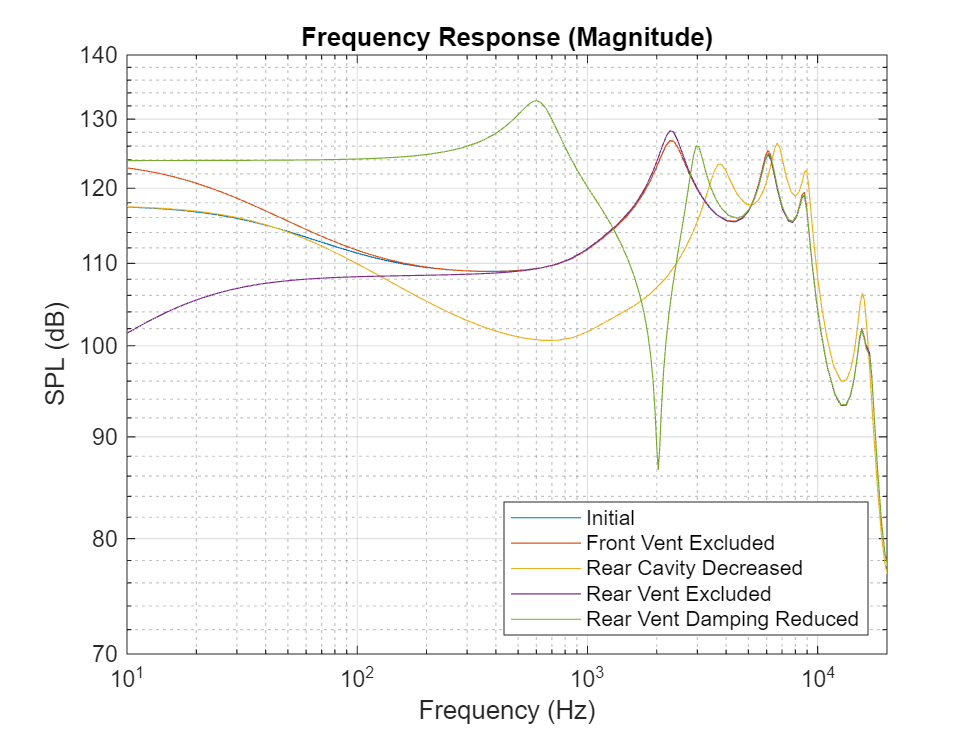

figure(fig1)
loglog(freq, SPL);
legend("Initial", ...
    "Front Vent Excluded", ...
    "Rear Cavity Decreased", ...
    "Rear Vent Excluded", ...
    "Rear Vent Damping Reduced", ...
    "Location","southeast");
hold on

Notice that the pressure response increases drastically from the low to mid frequency range as it was damped by the mesh. The resonance around 2kHz is shifted to lower frequency and a prominent dip shows up as expected.

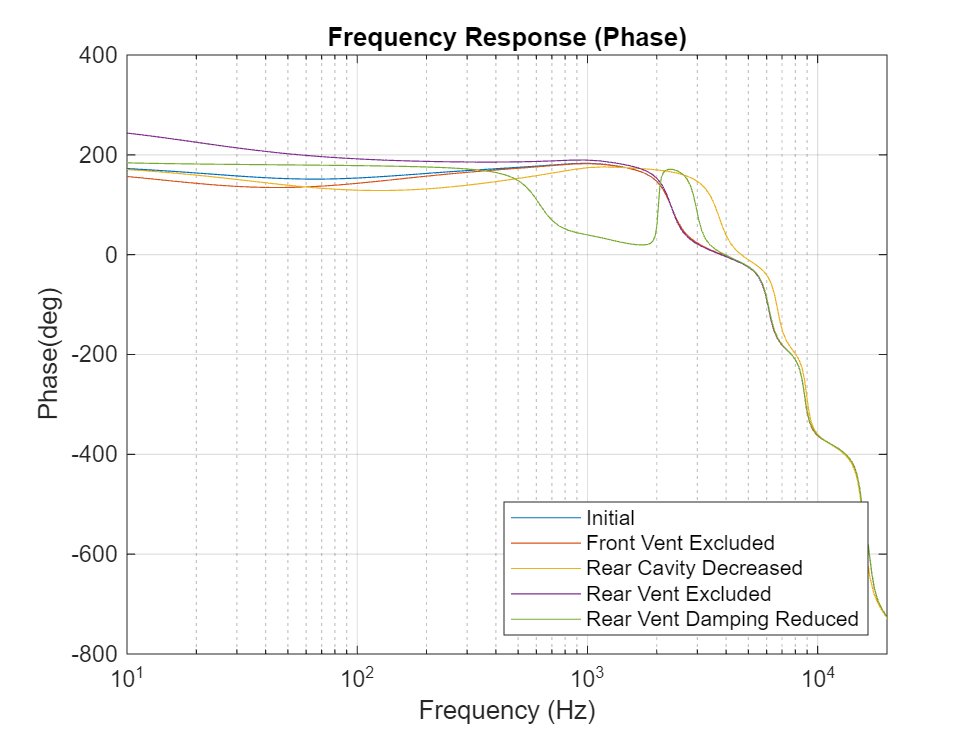

figure(fig2)
semilogx(freq, deg);
legend("Initial", ...
    "Front Vent Excluded", ...
    "Rear Cavity Decreased", ...
    "Rear Vent Excluded", ...
    "Rear Vent Damping Reduced", ...
    "Location","southeast");
hold on

## Increase Leakage

It is possible that the earbud is not perfectly fitted on the ear. The leakage can be modeled as a small cylindrical tube, which is essentially another front vent, comprising an inductor and resistor representing the air mass and air resistance respectively. 

The lumped values for the inertance and resistance of a small tube can be calculated by:


$$$M_{a}=\frac{4\rho l}{3A}$$$



$$$R_{a} = \frac{8\pi\rho\nu l}{A^2}$$$


where

- $$\rho$$ is the density of air $$1.21 kg/m^3$$.

- $$\nu$$ is the viscosity of air $$15.68\times10^{-6} m^2/s$$.

- $\;l\;$is the length of the tube.

- $A$ is the opening area of the tube.

The inductor and resistor are connected in series and parallel with the rest of the system.

To the see the influence of an imperfect fitting on frequency response, the radius of the leakage hole is increased by a factor of 10. From the equations above, the air inertance and resistance decrease as the opening area increases. And given the impedance for the two components:


$$\begin{array}{l}
Z_{\textrm{ma}} =j\omega \;M_a \\
Z_{\textrm{Ra}} =R_a 
\end{array}$$


where

- $\omega$ is the angular frequency.

The impedance is proportional to the component values. Thus, the air flow through the leakage branch will increase. This phenomenon is more prominent in the low frequency as the impedance is even smaller compared to high frequencies. So, the low frequency response is expected to decrease as the opening area of the leakage increases.

Restore the model to its previous state.

set_param(path2, 'R_r', "5.84e8");           % set rear vent damping value to previous state 

Increase the leakage.

set_param(path,'leak_r', 'leak_r*10');       % set parameter to increase the leakage by a factor of 10

Linearize the modified model.

linsys = linearize(model,io);           % linearize model
[mag, phase, wout] = bode(linsys);      % extract results
freq = wout./(2*pi);                    % convert radiance to frequency
SPL = 20.*log10(mag(:)./p_ref);         % calculate dBSPL
deg = phase(:);                         % extract phase 

Plot the results.

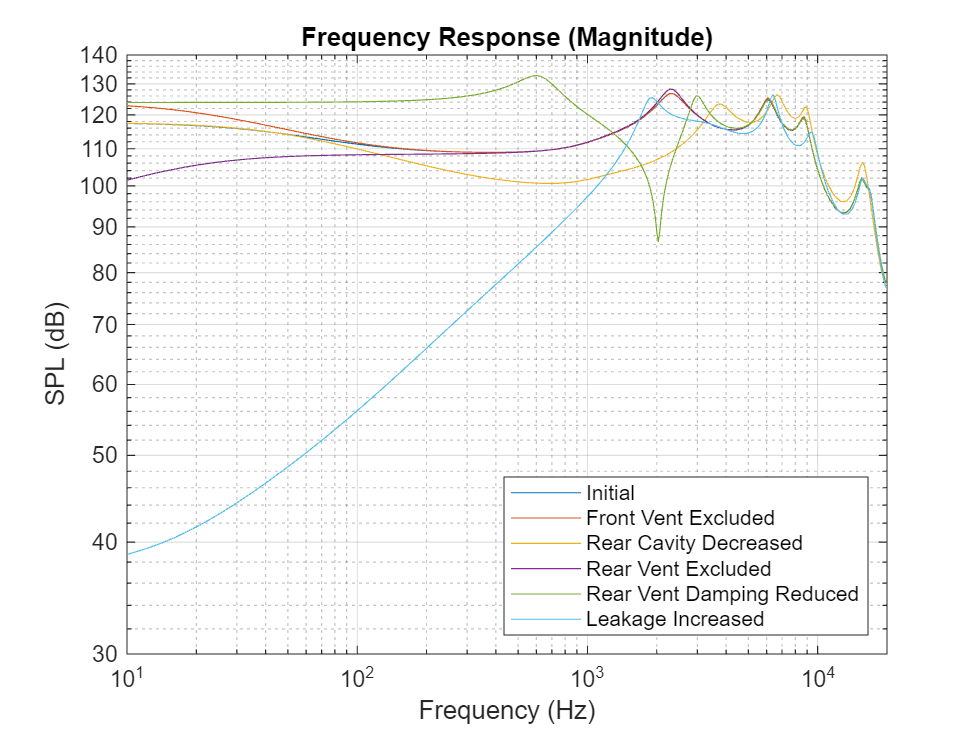

figure(fig1)
loglog(freq, SPL);
legend("Initial", ...
    "Front Vent Excluded", ...
    "Rear Cavity Decreased", ...
    "Rear Vent Excluded", ...
    "Rear Vent Damping Reduced", ...
    "Leakage Increased", ...
    "Location","southeast");
ylim([30 140]);
hold on

As shown in the plot, the low frequency response dropped drastically. In reality, the listener tends to loose the low frequency when the earbud is loosen from the ear, which agrees with the simulation results. 

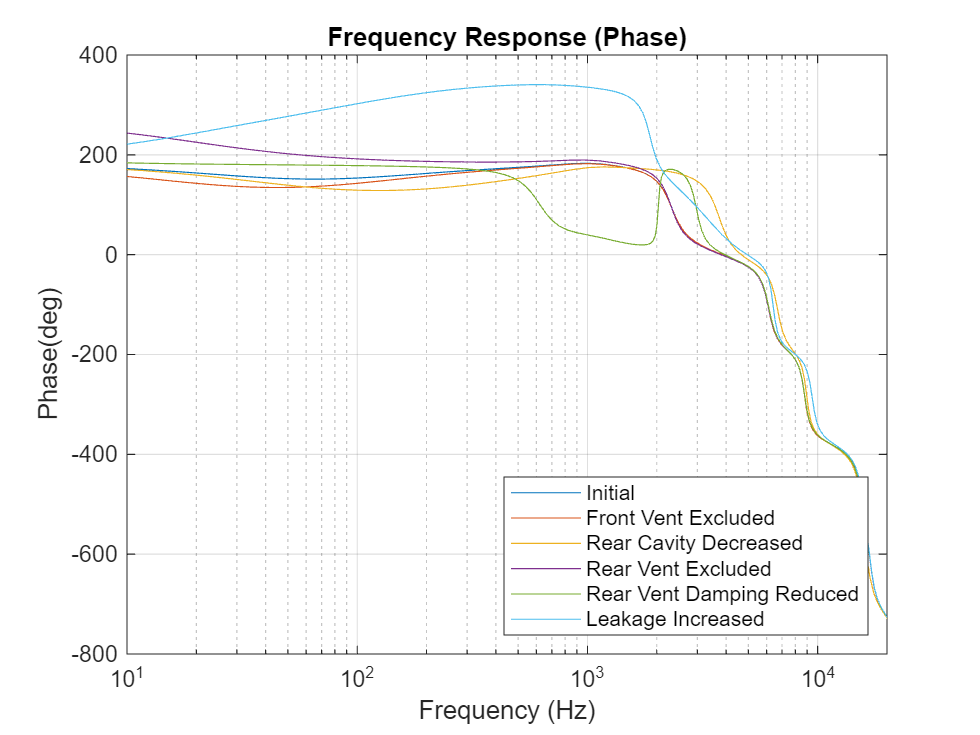

figure(fig2)
semilogx(freq, deg);
legend("Initial", ...
    "Front Vent Excluded", ...
    "Rear Cavity Decreased", ...
    "Rear Vent Excluded", ...
    "Rear Vent Damping Reduced", ...
    "Leakage Increased", ...
    "Location","southeast");
hold on

Close the system.

bdclose(model)

## References

Huang, Chen-Hung & Pawar, Suryappa & Hong, Zih-Jyun & Huang, Jin. (2011). Insert Earphone Modeling and Measurement by IEC-60711 Coupler. Ultrasonics, Ferroelectrics and Frequency Control, IEEE Transactions on. 58. 461 - 469. 10.1109/TUFFC.2011.1823.

*Copyright 2025 The MathWorks, Inc.*